# Visualizing the Data

Open data is everywhere!

Go to [https://data.melbourne.vic.gov.au/](https://data.melbourne.vic.gov.au/) and see how many data sources they have data on all aspects of Melbourne life! (seriously - look no further if you need to know the locations of all the public toilets, or the gradient of every footpath...)

**Example: data of pedestrian numbers in the CBD**

In this example we'll look at the dataset called 'Pedestrian Counts', which contains an hourly count for the number of people that passed a particular sensor in Melbourne. That's data every hour, on the hour at 18 locations, since 2009! And MATLAB didn't even bat an eyelid when I tried to load it up. (Ok, yes it did warn me I was opening a large text file, but it still worked).

**Sensor Locations**

- Bourke Street Mall (North)

- Bourke Street Mall (South)

- NA

- Town Hall (West)

- Princes Bridge

- Flinders Street Station Underpass

- NA

- NA

- Southern Cross Station

- Victoria Point

- Waterfront City

- New Quay

- Flagstaff Station

- Sandridge Bridge

- State Library

- Australia on Collins

- Collins Place (South)

- Collins Place (North)

Two tools that are used again and again when exploring data are scatter plots (`scatter`) and histograms (`hist` and `histc`). *NB both of these plots can also be achieved using the* `plot` *function*

## Scatter plots

The scatter plot command `scatter(x,y)` creates a scatter plot of the data points in the vectors x and y.

Let's use scatter to see if there is any correlation between North and South Bourke Street.

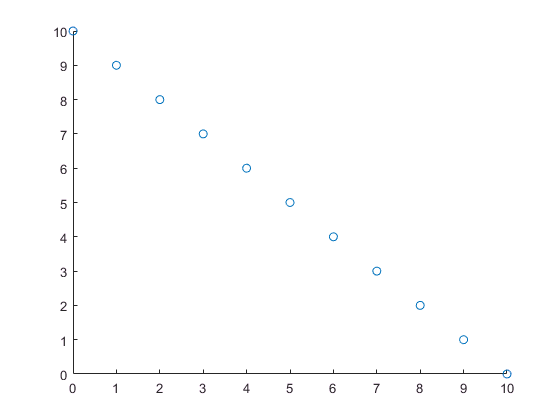

% First get the dates of both locations by indexing
% on their Sensor_ID value


% Similarly, we can use indexing to separate out the 
% count data for these specific locations

% We need to find out which dates we have that are 
% the same for both locations


% We only want to compare the count data from the dates
% that are the same for both locations

% We can check for correlation by looking at the scatter plot


MATLAB gives you a default scatter plot that looks something like this (we can pretty it up later, but for now we can clearly see that there is a relationship between North and South Bourke Street). 

## Challenge One

% CHALLENGE
% Create a scatter plot of two new locations

% EXTENSION TASKS
% Customize your plot - give it axis labels and 
% change the colors

## Histograms

The `histogram(data,bins)` plots a histogram of all the data points between the values of bins (i.e. `bins = 0:10:100` will create a histogram that goes from 0 to 100 with bins of width 10).

We're going to plot the distribution of foot traffic at Flinders Street station at different times of day. Flinders Street station is sensor number 6.

we can use `datevec` to convert the dates to vectors

We can convert all the dates and only select the hours want

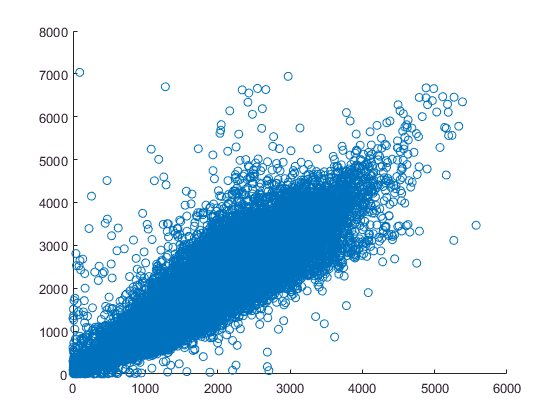

% get the dates as a vector


% The format is year-mon-day-hour-min-second


%Hour_SC = Dates_SC(:,4);

Let's look at the difference between 8am and 11am. We can pull out every measurement that was taken at 8am by indexing using our hour values in `Hour_Flinders`.

% Look at 8am vs 11am for Flinders St


We can display the two distributions as histograms using MATLABs default `hist` command

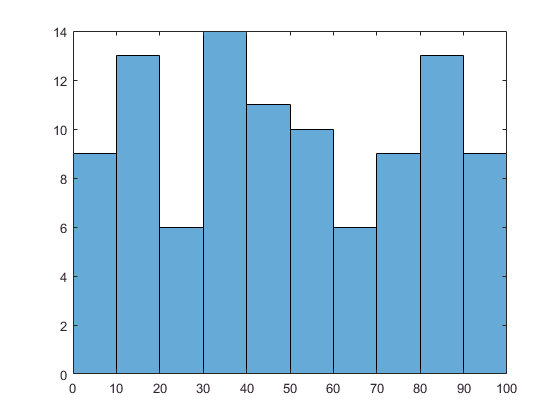

figure;

% plot the first distribution

% leave the plot in position

% plot the second distribution

ans = datetime
   01-May-2009


ans =         2009           5           1           0           0           0



% create a legend


Note that using the `hold on` command automatically assigns two different colors to the plots.

You can plot the probability density instead of counts on the y-axis using the option:

## Challenge Two

% CHALLENGE
% Plot histograms of two different times for at
% another location

% EXTENSION TASKS
% Plot histograms for 8am on Monday at Flinders Street
% and 8am on Sunday at Flinders Street
% HINT: The function 'weekday' will help a lot!

% Plot a scatter plot between 8am and 5pm
% at Flinders Street station to see if 
% there is any correlation

% Think of another question you're interested in 
% learning about from this data and make a plot!

## Challenge Three

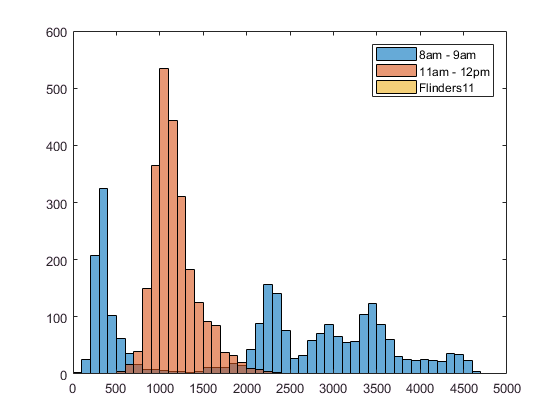

%% CHALLENGE
% Try download some other data you are interested in
% read it in and visualize some aspect. 
% You can use the user interface to try a few plots out, 
% but once you are happy with your plot write it in a
% script!